%load('avg20_runs-new')
%%% increase variance can help to enlarge ARCH cause this is square
%%% function
clear all;
close all;

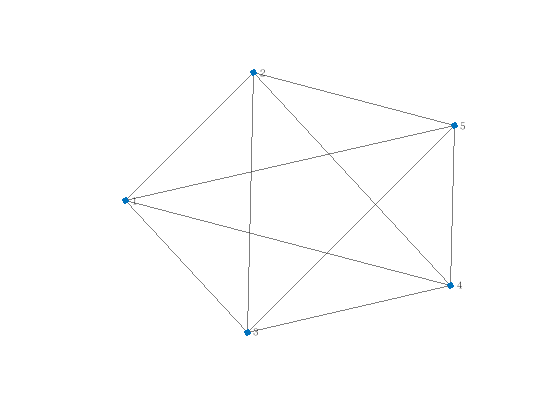


%graph topology
W = [0 1 1 1 1 ; 1 0 1 1 1; 1 1 0 1 1; 1 1 1 0 1;1 1 1 1 0];
D = diag(sum(W));
L = D-W;
N = size(L);
N = N(1);
figure();
G = graph(W);
plt = plot(G,'EdgeColor','black');
box off
set(gca,'Visible','off')

[V,D]=eig(L);
V_t = transpose(V);
%rng ('shuffle')
rng(6)


%data paramaters
numObs = 1000;
AR_Order = 2;
MA_Order = 1;
T = numObs;
length = T;
H = 6;
p = 1;
q = 1;

%%%%%%%past parameter
%     Mdl_1 = arima('Constant',3,'AR',{0.7 -0.2 0.4},'MA',{0.3},'Variance',garch('Constant',0.6,'GARCH',0.15,'ARCH',0.82));
%     V_1 = simulate(Mdl_1,numObs);
%     Mdl_2 = arima('Constant',1,'AR',{0.6 -0.1 0.3},'MA',{-0.5},'Variance',garch('Constant',0.5,'GARCH',0.2,'ARCH',0.75));
%     V_2 = simulate(Mdl_2,numObs);
%     Mdl_3 = arima('Constant',0.8,'AR',{0.2 0.1 0.6},'MA',{0.3},'Variance',garch('Constant',0.4,'GARCH',0.18,'ARCH',0.75));
%     V_3 = simulate(Mdl_3,numObs);
%     Mdl_4 = arima('Constant',-0.4,'AR',{0.4 0.15 0.4},'MA',{0.2},'Variance',garch('Constant',0.3,'GARCH',0.2,'ARCH',0.75));
%     V_4 = simulate(Mdl_4,numObs);
%     Mdl_5 = arima('Constant',-0.2,'AR',{0.2 -0.4 0.3},'MA',{-0.3},'Variance',garch('Constant',0.35,'GARCH',0.25,'ARCH',0.70));
%     V_5 = simulate(Mdl_5,numObs);

%     Mdl_1 = arima('Constant',10,'AR',{0.6 0.2 },'MA',{0.4},'Variance',garch('Constant',1,'GARCH',0.15,'ARCH',0.82));
%     [Y_1,E_1,V_1] = simulate(Mdl_1,numObs);
%     Mdl_2 = arima('Constant',0.1,'AR',{0.2 0.1 },'MA',{-0.2},'Variance',garch('Constant',0.3,'GARCH',0.2,'ARCH',0.75));
%     [Y_2,E_2,V_2] = simulate(Mdl_2,numObs);
%     Mdl_3 = arima('Constant',-0.02,'AR',{0.3 -0.2 },'MA',{0.3},'Variance',garch('Constant',0.15,'GARCH',0.2,'ARCH',0.75));
%     [Y_3,E_3,V_3] = simulate(Mdl_3,numObs);
%     Mdl_4 = arima('Constant',-0.01,'AR',{-0.2 0.5 },'MA',{-0.05},'Variance',garch('Constant',0.1,'GARCH',0.15,'ARCH',0.65));
%     [Y_4,E_4,V_4] = simulate(Mdl_4,numObs);
%     Mdl_5 = arima('Constant',0.01,'AR',{-0.2 0.5 },'MA',{-0.05},'Variance',garch('Constant',0.08,'GARCH',0.15,'ARCH',0.65));
%     [Y_5,E_5,V_5] = simulate(Mdl_4,numObs);
%     Xhat = [Y_1 Y_2 Y_3,Y_4,Y_5]';
%     res_hat = [E_1 E_2 E_3 E_4 E_5]';
%     X_signal = Xhat - res_hat;
%     not_IID = 1;
%     while(not_IID > 0)%iterate until abs(correlation)<0.1 except for the diagonals
%         val1 = abs(triu(corrcoef(res_hat')))-eye(N);
%         val2 = abs(triu(corrcoef(Xhat')))-eye(N);
%         [~,ind_found1] = find(val1>0.05, 1);
%         [~,ind_found2] = find(val2>0.05, 1);
%         for comp = 1:N
%             if comp == ind_found1
%                 m = ['Mdl_',num2str(comp)]
%                 Mdl_temp = eval(m);
%                 [Y_temp,E_temp,V_temp] = simulate(Mdl_temp,numObs);
%                 Xhat(comp,:) = Y_temp;
%                 res_hat(comp,:) = E_temp;
%             end
%             if comp == ind_found2 & ind_found1 ~= ind_found2
%                 m = ['Mdl_',num2str(comp)]
%                 Mdl_temp = eval(m);
%                 [Y_temp,E_temp,V_temp] = simulate(Mdl_temp,numObs);
%                 Xhat(comp,:) = Y_temp;
%                 res_hat(comp,:) = E_temp;
%             end
%         end
%         flag_a = sum(sum(abs(triu(corrcoef(res_hat')-eye(N)))));
%         flag_b = sum(sum(abs(triu(corrcoef(Xhat')-eye(N)))));
%         if flag_a <0.1 & flag_b < 0.1
%             not_IID = 0;
%         end
%     end

% 
% X_time = V*Xhat;
% C4 = cov(X_time')
% R4 = corrcoef(X_time')
% figure
% imagesc(R4);
% colorbar
% 
% H_arch = zeros(N,1);
% h_adf  = zeros(N,1);
% res_data = zeros(N,T);
% for i = 1:N
%     Mdl = arima(3,0,0);
%     EstMdl = estimate(Mdl,X_time(i,:)');
%     [res,~,logL] = infer(EstMdl,X_time(i,:)');
%     H_arch(i,1) = archtest(res);
%     h_adf(i,1) = adftest(X_time(i,:)');
%     res_data(i,:) = res';
% end
% 
% C1 = cov(X_signal')
% R1 = corrcoef(X_signal')
% figure
% imagesc(R1);
% colorbar
% 
% C2 = cov(Xhat')
% R2 = corrcoef(Xhat')
% imagesc(R2);
% colorbar
% 
% C3 = cov(res_hat')
% R3 = corrcoef(res_hat')
% figure
% imagesc(R3);
% colorbar
% fre = mean(abs(Xhat(:,:))')
% var1 = var((Xhat(:,:))')

% Mdl_1 = arima('Constant',-1.5,'AR',{0.8 0.1 },'MA',{0.4},'Variance',garch('Constant',0.02,'GARCH',0.10,'ARCH',0.85));
%     [Y_1,E_1,V_1] = simulate(Mdl_1,numObs);
%     Mdl_2 = arima('Constant',-0.3,'AR',{0.6 -0.4 },'MA',{-0.2},'Variance',garch('Constant',0.007,'GARCH',0.2,'ARCH',0.75));
%     [Y_2,E_2,V_2] = simulate(Mdl_2,numObs);
%     Mdl_3 = arima('Constant',-0.2,'AR',{-0.4 0.2 },'MA',{0.3},'Variance',garch('Constant',0.007,'GARCH',0.2,'ARCH',0.75));
%     [Y_3,E_3,V_3] = simulate(Mdl_3,numObs);
%     Mdl_4 = arima('Constant',0.1,'AR',{-0.3 0.4 },'MA',{-0.1},'Variance',garch('Constant',0.002,'GARCH',0.2,'ARCH',0.75));
%     [Y_4,E_4,V_4] = simulate(Mdl_4,numObs);
%     Mdl_5 = arima('Constant',0.05,'AR',{0.2 -0.1 },'MA',{0.2},'Variance',garch('Constant',0.002,'GARCH',0.15,'ARCH',0.80));
%     [Y_5,E_5,V_5] = simulate(Mdl_4,numObs);
%     Xhat = [Y_1 Y_2 Y_3,Y_4,Y_5]';
%     res_hat = [E_1 E_2 E_3 E_4 E_5]';

%     not_IID = 1;
%     X_signal = Xhat - res_hat;
%     iter =0;
%     while(not_IID > 0)%iterate until abs(correlation)<0.1 except for the diagonals
%         val1 = abs(triu(corrcoef(res_hat')))-eye(N);
% %         val2 = abs(triu(corrcoef(X_signal')))-eye(N);
%         [~,ind_found1] = find(val1>0.025);
% %         [~,ind_found2] = find(val2>0.05, 1);
%         column = unique(ind_found1)
%         for comp = 1:N
%             for j = 1:size(column,1)
%                  if comp == column(j,1)
%                     m = ['Mdl_',num2str(comp)]
%                     Mdl_temp = eval(m);
%                     [Y_temp,E_temp,V_temp] = simulate(Mdl_temp,numObs);
%                     Xhat(comp,:) = Y_temp;
%                     res_hat(comp,:) = E_temp;
%                     X_signal(comp,:) = Y_temp - E_temp;
%                 end               
%             end
% 
% %             if comp == ind_found2 & ind_found1 ~= ind_found2
% %                 m = ['Mdl_',num2str(comp)]
% %                 Mdl_temp = eval(m);
% %                 [Y_temp,E_temp,V_temp] = simulate(Mdl_temp,numObs);
% %                 Xhat(comp,:) = Y_temp;
% %                 res_hat(comp,:) = E_temp;
% %                 X_signal(comp,:) = Y_temp - E_temp;
% %             end
%         end
%         flag_a = sum(sum(abs(triu(corrcoef(res_hat')-eye(N)))));
% %         flag_b = sum(sum(abs(triu(corrcoef(Xhat')-eye(N)))));
% 
%         if flag_a < 0.2
%             not_IID = 0
%             val1 = abs(triu(corrcoef(res_hat')))-eye(N)
%         end
%     end
%     
%     X_time = V*Xhat;

% Final parameters
% Mdl_1 = arima('Constant',-1.5,'AR',{0.8 0.1 },'MA',{0.4},'Variance',garch('Constant',0.02,'GARCH',0.05,'ARCH',0.90));
%     [Y_1,E_1,V_1] = simulate(Mdl_1,numObs);
%     Mdl_2 = arima('Constant',-0.3,'AR',{0.6 -0.4 },'MA',{-0.2},'Variance',garch('Constant',0.007,'GARCH',0.10,'ARCH',0.85));
%     [Y_2,E_2,V_2] = simulate(Mdl_2,numObs);
%     Mdl_3 = arima('Constant',-0.2,'AR',{-0.4 0.2 },'MA',{0.3},'Variance',garch('Constant',0.007,'GARCH',0.10,'ARCH',0.85));
%     [Y_3,E_3,V_3] = simulate(Mdl_3,numObs);
%     Mdl_4 = arima('Constant',0.1,'AR',{-0.3 0.4 },'MA',{-0.1},'Variance',garch('Constant',0.002,'GARCH',0.10,'ARCH',0.85));
%     [Y_4,E_4,V_4] = simulate(Mdl_4,numObs);
%     Mdl_5 = arima('Constant',0.05,'AR',{0.2 -0.1 },'MA',{0.2},'Variance',garch('Constant',0.002,'GARCH',0.15,'ARCH',0.8));
%     [Y_5,E_5,V_5] = simulate(Mdl_5,numObs);

%train/test split ratio
sample_rate = 0.8;
index_in = ceil(length* sample_rate);
test_L = length  - index_in;
RUNS = 50;
all_avg_MAE_ARMA = zeros(H,1);
all_avg_MAE_G_VARMA = zeros(H,1);
all_avg_MAE_GARCH = zeros(H,1);
all_avg_MAE_G_GARCH = zeros(H,1);
all_avg_rNMSE_ARMA = zeros(H,1);
all_avg_rNMSE_GARCH = zeros(H,1);
all_avg_rNMSE_G_VARMA = zeros(H,1);
all_avg_rNMSE_G_GARCH = zeros(H,1);
Options = optimoptions(@fmincon,'ConstraintTolerance',1e-3,'Algorithm','sqp');

for runs = 1:RUNS
    Prediction_spectral_VARMA = zeros(N,test_L,H);
    Prediction_spectral_G_GARCH= zeros(N,test_L,H);
    Prediction_time_ARMA = zeros(N,test_L,H);
    Prediction_time_GARCH = zeros(N,test_L,H);
    %initialization of data

    Mdl_1 = arima('Constant',-1.5,'AR',{0.8 0.1 },'MA',{0.4},'Variance',garch('Constant',0.02,'GARCH',0.05,'ARCH',0.90));
    [Y_1,E_1,V_1] = simulate(Mdl_1,numObs);
    Mdl_2 = arima('Constant',-0.3,'AR',{0.6 -0.4 },'MA',{-0.2},'Variance',garch('Constant',0.007,'GARCH',0.10,'ARCH',0.85));
    [Y_2,E_2,V_2] = simulate(Mdl_2,numObs);
    Mdl_3 = arima('Constant',-0.2,'AR',{-0.4 0.2 },'MA',{0.3},'Variance',garch('Constant',0.007,'GARCH',0.10,'ARCH',0.85));
    [Y_3,E_3,V_3] = simulate(Mdl_3,numObs);
    Mdl_4 = arima('Constant',0.1,'AR',{-0.3 0.4 },'MA',{-0.1},'Variance',garch('Constant',0.002,'GARCH',0.10,'ARCH',0.85));
    [Y_4,E_4,V_4] = simulate(Mdl_4,numObs);
    Mdl_5 = arima('Constant',0.05,'AR',{0.2 -0.1 },'MA',{0.2},'Variance',garch('Constant',0.002,'GARCH',0.15,'ARCH',0.8));
    [Y_5,E_5,V_5] = simulate(Mdl_5,numObs);
    Xhat = [Y_1 Y_2 Y_3,Y_4,Y_5]';
    res_hat = [E_1 E_2 E_3 E_4 E_5]';
    not_IID = 1;
    X_signal = Xhat - res_hat;
    iter =0;
    while(not_IID > 0)%iterate until abs(correlation)<0.1 except for the diagonals
        val1 = abs(triu(corrcoef(res_hat')))-eye(N);
%         val2 = abs(triu(corrcoef(X_signal')))-eye(N);
        [~,ind_found1] = find(val1>0.025);
%         [~,ind_found2] = find(val2>0.05, 1);
        column = unique(ind_found1)
        for comp = 1:N
            for j = 1:size(column,1)
                 if comp == column(j,1)
                    m = ['Mdl_',num2str(comp)]
                    Mdl_temp = eval(m);
                    [Y_temp,E_temp,V_temp] = simulate(Mdl_temp,numObs);
                    Xhat(comp,:) = Y_temp;
                    res_hat(comp,:) = E_temp;
                    X_signal(comp,:) = Y_temp - E_temp;
                end               
            end

%             if comp == ind_found2 & ind_found1 ~= ind_found2
%                 m = ['Mdl_',num2str(comp)]
%                 Mdl_temp = eval(m);
%                 [Y_temp,E_temp,V_temp] = simulate(Mdl_temp,numObs);
%                 Xhat(comp,:) = Y_temp;
%                 res_hat(comp,:) = E_temp;
%                 X_signal(comp,:) = Y_temp - E_temp;
%             end
        end
        flag_a = sum(sum(abs(triu(corrcoef(res_hat')-eye(N)))));
%         flag_b = sum(sum(abs(triu(corrcoef(Xhat')-eye(N)))));

        if isempty(ind_found1) && (flag_a <0.25) 
            not_IID = 0
            val1 = abs(triu(corrcoef(res_hat')))-eye(N)
        end
    end
    
    X_time = V*Xhat;
    %split data
    X_test_time = V*Xhat(:,index_in+1:end);
    X_test_spectral = Xhat(:,index_in+1:end);

    %G-VARMA and G-GARCH training
    for i = 1:1:N
        X_train = Xhat(i,1:index_in)';
        X_time_temp = X_time(i,1:index_in)';
        Mdl_ARMA = arima(AR_Order,0,MA_Order);
%         [~,EstMdl_ARMA,~,~] = evalc('estimate(Mdl_ARMA,X_train,''options'',Options);');
        EstMdl_ARMA = estimate(Mdl_ARMA,X_time_temp,'options',Options);
%         [res_ARMA(:,i),~,logL] = infer(EstMdl_ARMA,X_train);
        for index = 1:1:length - index_in
            for j = 1:1:H
                if j == 1
                    Prediction_time_ARMA(i,index,j) =forecast(EstMdl_ARMA,j,'Y0',X_time(i,1:index_in -j +index)');
                else
                    temp = forecast(EstMdl_ARMA,j,'Y0',X_time(i,1:index_in -j +index)');
                    Prediction_time_ARMA(i,index,j) = temp(j,1);
                end
            end
        end
        Mdl_GARCH = arima('ARLags',[1,2],'MALags',1,'Variance',garch(1,1));
%         [~,EstMdl_GARCH,~,~] = evalc('estimate(Mdl_GARCH,X_train,''options'',Options);');
        EstMdl_GARCH = estimate(Mdl_GARCH,X_time_temp,'options',Options);
%         [res_GARCH(:,i),~,logL] = infer(EstMdl_GARCH,X_train);
        for index = 1:1:length - index_in
            for j = 1:1:H
                if j == 1
                    Prediction_time_GARCH(i,index,j) =forecast(EstMdl_GARCH,j,'Y0',X_time(i,1:index_in -j +index)');
                else
                    temp = forecast(EstMdl_GARCH,j,'Y0',X_time(i,1:index_in -j +index)');
                    Prediction_time_GARCH(i,index,j) = temp(j,1);
                end
            end
        end
        Mdl_VARMA = arima(AR_Order,0,MA_Order);
%         [~,EstMdl_VARMA,~,~] = evalc('estimate(Mdl_VARMA,X_train,''options'',Options);');
        EstMdl_VARMA = estimate(Mdl_VARMA,X_train,'options',Options);
%         [res_VARMA(:,i),~,logL] = infer(EstMdl_VARMA,X_train);
        for index = 1:1:length - index_in
            for j = 1:1:H
                if j == 1
                    Prediction_spectral_VARMA(i,index,j) =forecast(EstMdl_VARMA,j,'Y0',Xhat(i,1:index_in -j +index)');
                else
                    temp = forecast(EstMdl_VARMA,j,'Y0',Xhat(i,1:index_in -j +index)');
                    Prediction_spectral_VARMA(i,index,j) = temp(j,1);
                end
            end
        end
        Mdl_G_GARCH = arima('ARLags',[1,2],'MALags',1,'Variance',garch(1,1));
%         [~,EstMdl_G_GARCH,~,~] = evalc('estimate(Mdl_G_GARCH,X_train,''options'',Options);');
        EstMdl_G_GARCH = estimate(Mdl_G_GARCH,X_train,'options',Options);
%         [res_G_GARCH(:,i),~,logL] = infer(EstMdl_G_GARCH,X_train);
        for index = 1:1:length - index_in
            for j = 1:1:H
                if j == 1
                    Prediction_spectral_G_GARCH(i,index,j) =forecast(EstMdl_G_GARCH,j,'Y0',Xhat(i,1:index_in -j +index)');
                else
                    temp = forecast(EstMdl_G_GARCH,j,'Y0',Xhat(i,1:index_in -j +index)');
                    Prediction_spectral_G_GARCH(i,index,j) = temp(j,1);
                end
            end
        end    
    end
    %G-VARMA and G-GARCH testing/forecasting
    Prediction_time_VARMA = zeros(N,test_L,H);
    Prediction_time_G_GARCH= zeros(N,test_L,H);
    for horizon = 1:H
        Prediction_time_VARMA(:,:,horizon) = V*Prediction_spectral_VARMA(:,:,horizon);
        Prediction_time_G_GARCH(:,:,horizon) = V*Prediction_spectral_G_GARCH(:,:,horizon);
    end
    %MAE and rNMSE 1 run
    error_vec_horizon_ARMA = zeros(N,test_L,H);
    MAE_ARMA = zeros(N,H);
    avg_MAE_ARMA = zeros(H,1);
    rNMSE_ARMA = zeros(N,H);
    avg_rNMSE_ARMA = zeros(H,1);
    for i = 1:1:H
        error_vec_horizon_ARMA(:,:,i) = abs(Prediction_time_ARMA(:,:,i) - X_test_time(:,:));
        MAE_ARMA(:,i)  = sum(error_vec_horizon_ARMA(:,:,i),2)/(test_L);
        avg_MAE_ARMA(i) = sum(MAE_ARMA(:,i))/N;
        rNMSE_ARMA(:,i) = sqrt(sum(error_vec_horizon_ARMA(:,:,i).^2,2)./sum(X_test_time(:,:).^2,2));
        avg_rNMSE_ARMA(i) = sqrt(sum(sum(error_vec_horizon_ARMA(:,:,i).^2,2))/sum(sum(X_test_time(:,:).^2,2)));
    end
        error_vec_horizon_GARCH = zeros(N,test_L,H);
    MAE_GARCH = zeros(N,H);
    avg_MAE_GARCH = zeros(H,1);
    rNMSE_GARCH = zeros(N,H);
    avg_rNMSE_GARCH = zeros(H,1);
    for i = 1:1:H
        error_vec_horizon_GARCH(:,:,i) = abs(Prediction_time_GARCH(:,:,i) - X_test_time(:,:));
        MAE_GARCH(:,i)  = sum(error_vec_horizon_GARCH(:,:,i),2)/(test_L);
        avg_MAE_GARCH(i) = sum(MAE_GARCH(:,i))/N;
        rNMSE_GARCH(:,i) = sqrt(sum(error_vec_horizon_GARCH(:,:,i).^2,2)./sum(X_test_time(:,:).^2,2));
        avg_rNMSE_GARCH(i) = sqrt(sum(sum(error_vec_horizon_GARCH(:,:,i).^2,2))/sum(sum(X_test_time(:,:).^2,2)));
    end
    error_vec_horizon_VARMA = zeros(N,test_L,H);
    MAE_G_VARMA = zeros(N,H);
    avg_MAE_G_VARMA = zeros(H,1);
    rNMSE_G_VARMA = zeros(N,H);
    avg_rNMSE_G_VARMA = zeros(H,1);
    for i = 1:1:H
        error_vec_horizon_VARMA(:,:,i) = abs(Prediction_time_VARMA(:,:,i) - X_test_time(:,:));
        MAE_G_VARMA(:,i)  = sum(error_vec_horizon_VARMA(:,:,i),2)/(test_L);
        avg_MAE_G_VARMA(i) = sum(MAE_G_VARMA(:,i))/N;
        rNMSE_G_VARMA(:,i) = sqrt(sum(error_vec_horizon_VARMA(:,:,i).^2,2)./sum(X_test_time(:,:).^2,2));
        avg_rNMSE_G_VARMA(i) = sqrt(sum(sum(error_vec_horizon_VARMA(:,:,i).^2,2))/sum(sum(X_test_time(:,:).^2,2)));
    end
    error_vec_horizon_G_GARCH = zeros(N,test_L,H);
    MAE_H_G_GARCH = zeros(N,H);
    avg_MAE_H_G_GARCH = zeros(H,1);
    rNMSE_H_G_GARCH = zeros(N,H);
    avg_rNMSE_H_G_GARCH = zeros(H,1);
    for i = 1:1:H
        error_vec_horizon_G_GARCH(:,:,i) = abs(Prediction_time_G_GARCH(:,:,i) - X_test_time(:,:));
        MAE_H_G_GARCH(:,i)  = sum(error_vec_horizon_G_GARCH(:,:,i),2)/(test_L);
        avg_MAE_H_G_GARCH(i) = sum(MAE_H_G_GARCH(:,i))/N;
        rNMSE_H_G_GARCH(:,i) = sqrt(sum(error_vec_horizon_G_GARCH(:,:,i).^2,2)./sum(X_test_time(:,:).^2,2));
        avg_rNMSE_H_G_GARCH(i) = sqrt(sum(sum(error_vec_horizon_G_GARCH(:,:,i).^2,2))/sum(sum(X_test_time(:,:).^2,2)));
    end
    all_avg_MAE_ARMA = all_avg_MAE_ARMA+avg_MAE_ARMA;
    all_avg_MAE_GARCH = all_avg_MAE_GARCH+avg_MAE_GARCH;
    all_avg_MAE_G_VARMA = all_avg_MAE_G_VARMA+avg_MAE_G_VARMA;
    all_avg_MAE_G_GARCH = all_avg_MAE_G_GARCH+avg_MAE_H_G_GARCH;
    all_avg_rNMSE_ARMA = all_avg_rNMSE_ARMA+avg_rNMSE_ARMA;
    all_avg_rNMSE_GARCH = all_avg_rNMSE_GARCH+avg_rNMSE_GARCH;
    all_avg_rNMSE_G_VARMA = all_avg_rNMSE_G_VARMA+avg_rNMSE_G_VARMA;
    all_avg_rNMSE_G_GARCH = all_avg_rNMSE_G_GARCH+avg_rNMSE_H_G_GARCH;
end
all_avg_MAE_ARMA = all_avg_MAE_ARMA./RUNS;
all_avg_MAE_GARCH = all_avg_MAE_GARCH./RUNS;
all_avg_MAE_G_VARMA = all_avg_MAE_G_VARMA./RUNS;
all_avg_MAE_G_GARCH = all_avg_MAE_G_GARCH./RUNS;
all_avg_rNMSE_ARMA = all_avg_rNMSE_ARMA./RUNS;
all_avg_rNMSE_GARCH = all_avg_rNMSE_GARCH./RUNS;
all_avg_rNMSE_G_VARMA = all_avg_rNMSE_G_VARMA./RUNS;
all_avg_rNMSE_G_GARCH = all_avg_rNMSE_G_GARCH./RUNS;

%%%% Average improvement 50 run
avgratio_MAE = zeros(1,H);
avgratio_rNMESE = zeros(1,H);
for j = 1:H
    avgratio_MAE(j) = (all_avg_MAE_G_VARMA(j) - all_avg_MAE_G_GARCH(j))./all_avg_MAE_G_VARMA(j);
    avgratio_rNMESE(j) = (all_avg_rNMSE_G_VARMA(j)-all_avg_rNMSE_G_GARCH(j))./all_avg_rNMSE_G_VARMA(j);
end

figure();
plot(all_avg_MAE_G_GARCH);
hold on;
plot(all_avg_MAE_G_VARMA);
plot(all_avg_MAE_ARMA);
plot(all_avg_MAE_GARCH);
legend('G-GARCH','G-VARMA','ARMA','GARCH','Location','southeast');
xlabel('k-step ahead forecast');
ylabel('MAE');
xlim([0 6]);
% ylim([0 0.26]);
%savefig('MAE.fig');

figure();
plot(all_avg_rNMSE_G_GARCH);
hold on;
plot(all_avg_rNMSE_G_VARMA);
plot(all_avg_rNMSE_ARMA);
plot(all_avg_rNMSE_GARCH);
legend('G-GARCH','G-VARMA','ARMA','GARCH','Location','southeast');
xlabel('k-step ahead forecast');
ylabel('rNMSE');
xlim([0 6]);
% ylim([0 0.05]);
%savefig('rNMSE.fig');

%save('avg20_runs-new')
%save('avg20_runs-ar2-garch11')
%load('avg20_runs-ar2-garch11')
%save('avg50_runs-ar2-garch11')
%save('avg100_runs-ar2-garch11')

%load('avg50_runs-ar2-garch11')